# **IRB140 WORK SPACE**

**Team: **Jose García Torres & Iván López Buira **[Group 11-F]**

**Link shared folder: **[https://drive.mathworks.com/sharing/09b55873-900d-4ef4-a139-6397e28575bd](https://drive.mathworks.com/sharing/09b55873-900d-4ef4-a139-6397e28575bd)

### Step 1: Invoque IRB140 

clear
close all
mdl_irb140

 
robot = 
 
IRB 140 [ABB]:: 6 axis, RRRRRR, stdDH, slowRNE                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.352|       0.07|    -1.5708|          0|
|  2|         q2|          0|       0.36|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|       0.38|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


### Step 2: Plot the IRB 140

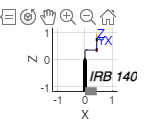

irb140.plot(qz,'zoom',2, 'view',[0 0])

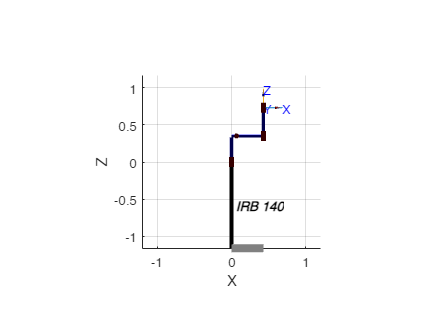

Pay attention to home position of the ABB Drawing and the wired model of the RTB

To think about

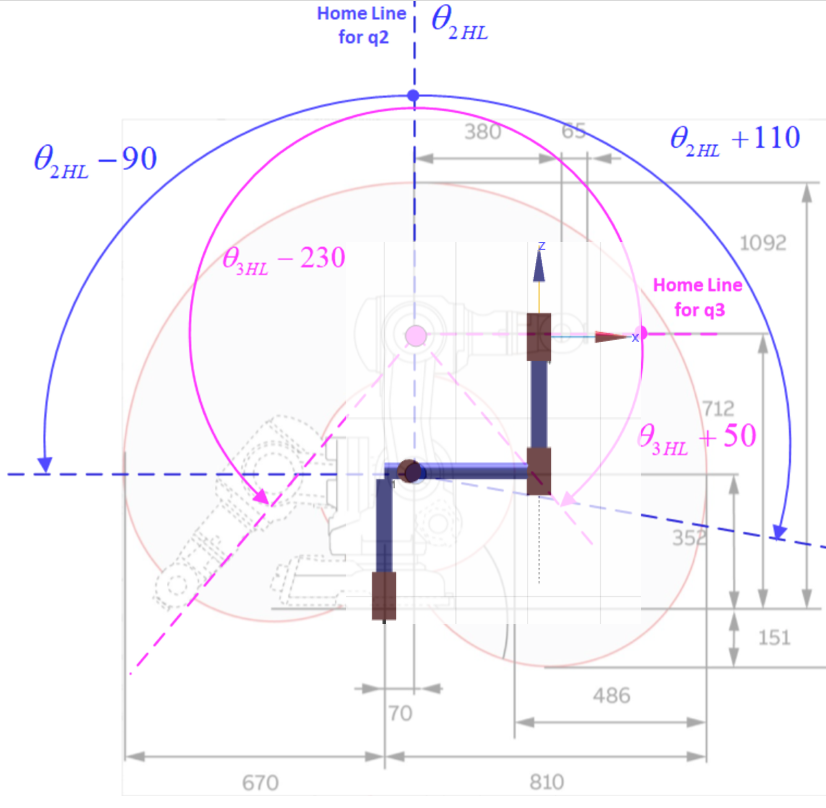

### Step 3: Use the teach

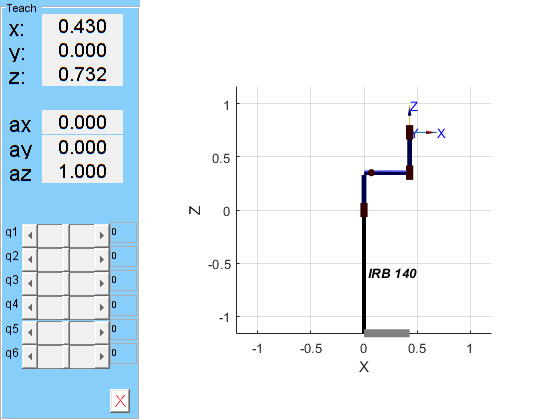

irb140.teach('approach')

### Step 4: Fill the table

Understand the numbers that appears in the following table and fill/create a matrix with the irb140RTB angles.

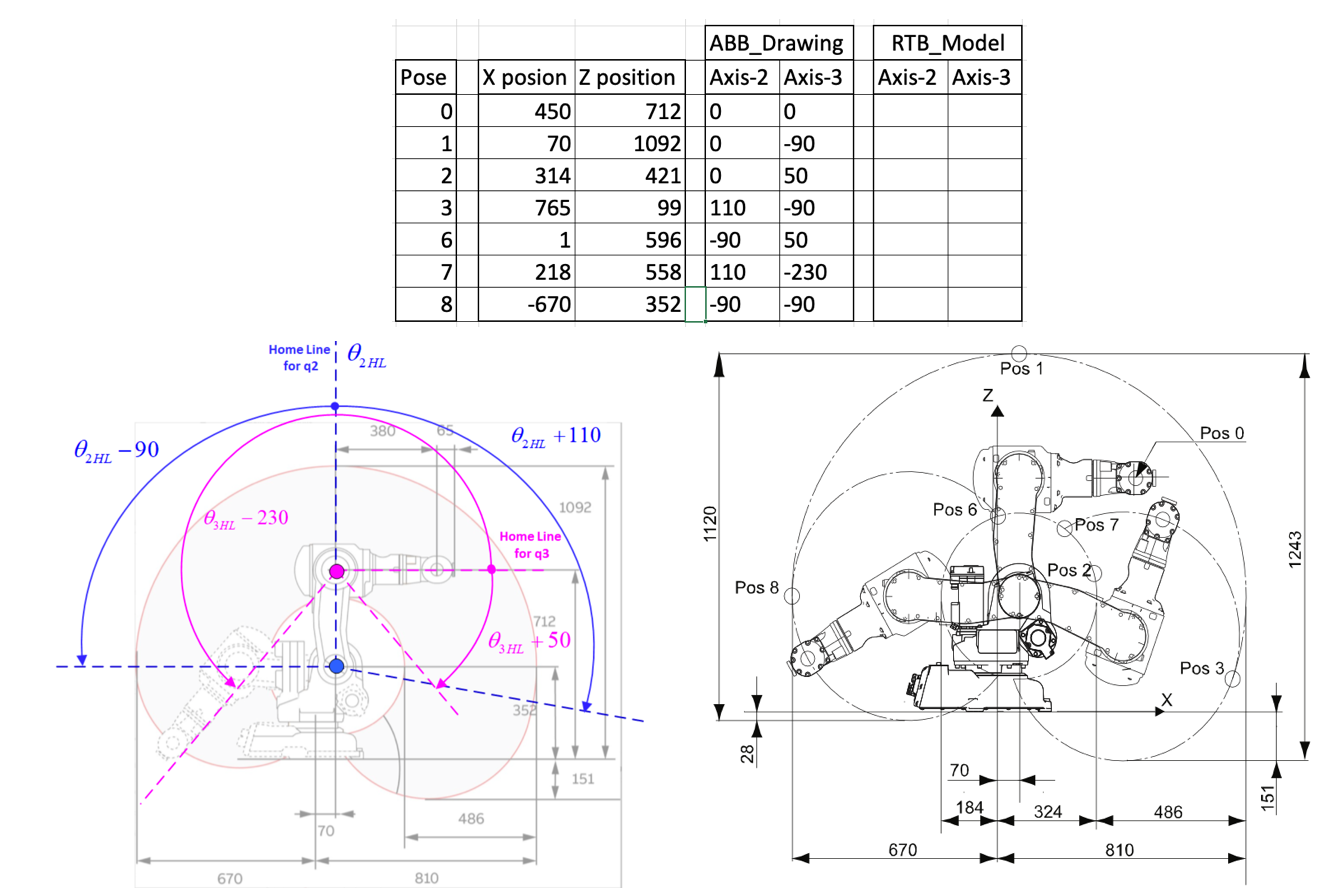

**RTB_MODEL AXIS ANGLES:**

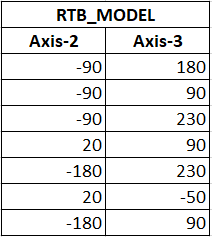

### Clculate join limits:

 q2 and q3:

irb140.links(1,2).qlim = [deg2rad(-180), deg2rad(20)] % q2

 
irb140 = 
 
IRB 140 [ABB]:: 6 axis, RRRRRR, stdDH, slowRNE                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.352|       0.07|    -1.5708|          0|
|  2|         q2|          0|       0.36|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|       0.38|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


irb140.links(1,3).qlim = [deg2rad(-50), deg2rad(230)] % q3

 
irb140 = 
 
IRB 140 [ABB]:: 6 axis, RRRRRR, stdDH, slowRNE                   
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|         q1|      0.352|       0.07|    -1.5708|          0|
|  2|         q2|          0|       0.36|          0|          0|
|  3|         q3|          0|          0|     1.5708|          0|
|  4|         q4|       0.38|          0|    -1.5708|          0|
|  5|         q5|          0|          0|     1.5708|          0|
|  6|         q6|          0|          0|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 



q2_limits = irb140.links(1,2).qlim

q2_limits =    -3.1416    0.3491


q3_limits = irb140.links(1,3).qlim

q3_limits =    -0.8727    4.0143


**MOVE THE ROBOT:**

Q = zeros(100,6)

Q =      0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0
     0     0     0     0     0     0


Q(1,2:3) = [q2_limits(1) q3_limits(2)]

Q =          0   -3.1416    4.0143         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0



Q(1:20, 2:3) = [linspace(q2_limits(1),q2_limits(2),20)' linspace(q3_limits(2),q3_limits(2),20)']

Q =          0   -3.1416    4.0143         0         0         0
         0   -2.9579    4.0143         0         0         0
         0   -2.7742    4.0143         0         0         0
         0   -2.5904    4.0143         0         0         0
         0   -2.4067    4.0143         0         0         0
         0   -2.2230    4.0143         0         0         0
         0   -2.0393    4.0143         0         0         0
         0   -1.8556    4.0143         0         0         0
         0   -1.6718    4.0143         0         0         0
         0   -1.4881    4.0143         0         0         0



Q(21:40, 2:3) = [linspace(q2_limits(2),q2_limits(2),20)' linspace(q3_limits(2),deg2rad(90),20)']

Q =          0   -3.1416    4.0143         0         0         0
         0   -2.9579    4.0143         0         0         0
         0   -2.7742    4.0143         0         0         0
         0   -2.5904    4.0143         0         0         0
         0   -2.4067    4.0143         0         0         0
         0   -2.2230    4.0143         0         0         0
         0   -2.0393    4.0143         0         0         0
         0   -1.8556    4.0143         0         0         0
         0   -1.6718    4.0143         0         0         0
         0   -1.4881    4.0143         0         0         0



Q(41:60, 2:3) = [linspace(q2_limits(2),q2_limits(1),20)' linspace(deg2rad(90),deg2rad(90),20)']

Q =          0   -3.1416    4.0143         0         0         0
         0   -2.9579    4.0143         0         0         0
         0   -2.7742    4.0143         0         0         0
         0   -2.5904    4.0143         0         0         0
         0   -2.4067    4.0143         0         0         0
         0   -2.2230    4.0143         0         0         0
         0   -2.0393    4.0143         0         0         0
         0   -1.8556    4.0143         0         0         0
         0   -1.6718    4.0143         0         0         0
         0   -1.4881    4.0143         0         0         0



Q(61:80, 2:3) = [linspace(q2_limits(1),q2_limits(1),20)' linspace(deg2rad(90),q3_limits(1),20)']

Q =          0   -3.1416    4.0143         0         0         0
         0   -2.9579    4.0143         0         0         0
         0   -2.7742    4.0143         0         0         0
         0   -2.5904    4.0143         0         0         0
         0   -2.4067    4.0143         0         0         0
         0   -2.2230    4.0143         0         0         0
         0   -2.0393    4.0143         0         0         0
         0   -1.8556    4.0143         0         0         0
         0   -1.6718    4.0143         0         0         0
         0   -1.4881    4.0143         0         0         0



Q(81:100, 2:3) = [linspace(q2_limits(1),q2_limits(2),20)' linspace(q3_limits(1),q3_limits(1),20)']

Q =          0   -3.1416    4.0143         0         0         0
         0   -2.9579    4.0143         0         0         0
         0   -2.7742    4.0143         0         0         0
         0   -2.5904    4.0143         0         0         0
         0   -2.4067    4.0143         0         0         0
         0   -2.2230    4.0143         0         0         0
         0   -2.0393    4.0143         0         0         0
         0   -1.8556    4.0143         0         0         0
         0   -1.6718    4.0143         0         0         0
         0   -1.4881    4.0143         0         0         0


**VISUALIZE WORK AREA:**

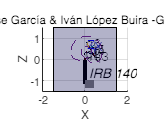

figure
hold on
v = [-1.5 -0.1501 -1.5 ; 1.5 -0.1501 -1.5 ; 1.5 -0.1501 1.5; -1.5 -0.1501 1.5];
f = [1 2 3 4];
patch('Faces',f,'Vertices',v,'FaceColor','blue','FaceAlpha',.3)
title ('Jose García & Iván López Buira -G11 F')
irb140.plot(Q,'trail','--','jaxes','zoom',2,'view', [0,0], 'movie', 'irb140_workspace_G11F.mp4')

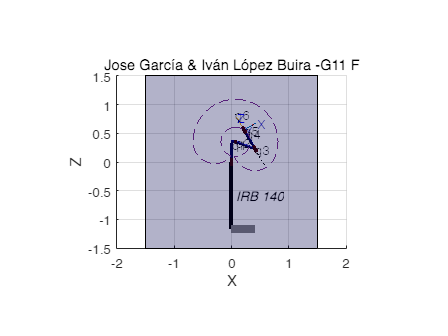

**RECOVERING END EFECTOR:**

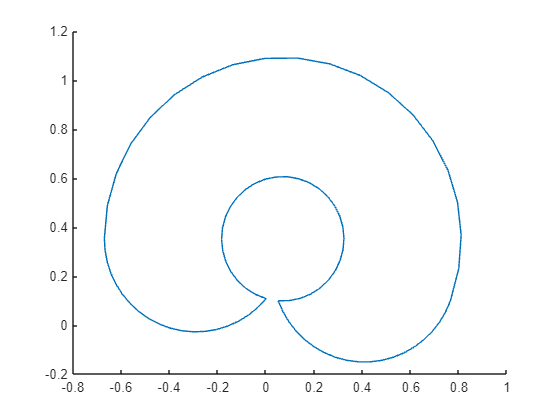

T=irb140.fkine(Q);
ft=[T.t]

figure
plot3(ft(1,:),ft(2,:), ft(3,:))
view(0,0)